# 4.2.3 break和continue 

- **break**`关键字``用于终止执行` for `或` while `循环。`

- **continue**`关键字``用于跳过循环的当前迭代，然后继续下一次迭代。`

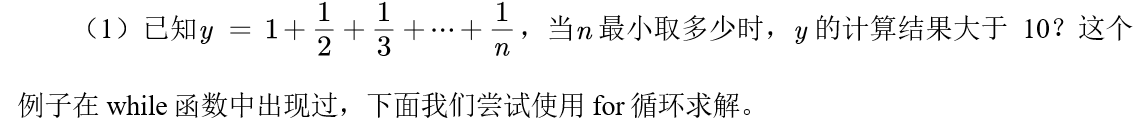

y = 0;
for n = 1:1e8
    y = y + 1/n;
    if y > 10
        disp(n)
        break  % 退出for循环
    end  % if配套的end
end  % for配套的end

`（`2`）使用循环输出`1`至`10`中所有的奇数。`

for i = 1:10
    if mod(i, 2) == 0
        continue
    end
    disp(i)
end

for i = 1:10
    if mod(i, 2) == 1
        disp(i)
    end
end

注意，如果存在循环的嵌套，break和continue 仅在调用它的循环的主体中起作用。即break 仅从它所发生的循环中退出，continue 仅跳过它所发生的循环体内的剩余语句。

for ii = 1:2  % 外循环
    for jj = 1:3  % 内循环
        if jj <= ii
            disp(ii)
            disp(jj)
        else
            break
        end  % if配套的end
    end  % 内循环配套的end
end  % 外循环配套的end

思考，下面这段代码的运行结果是什么？

for ii = 1:2
    for jj = 1:3
        if jj > ii
            continue 
        end
        disp(ii)
        disp(jj)
    end
end

`（`1`）判断质数问题`

n = 135389;  % 输入要判断的数n
is_prime = true;   % 初始化标志变量is_prime为true，此时代表n是质数
for ii = 2:n-1  % 思考：如何缩小循环遍历的范围来提高代码运行的效率，留作本章课后习题
    % 检查ii是否能够整除n
    if mod(n, ii) == 0
        % 如果能整除，则n不是质数，将标志变量is_prime重新赋值为false
        is_prime = false;
        break;  % 跳出循环
    end
end
disp(is_prime)

内置函数

isprime(n)

`（`2`）扑克牌炸弹问题`

% 用1至13分别代替A 2 3 ... J Q K, 重复4次表示四种花色；用14和15分别代表大小王
poke = [repmat(1:13,1,4),14,15]  % 生成一副扑克牌
% 也可以使用repelem函数
% poke = [repelem(1:13,1,4),14,15] 
k = 1;  % 玩了多少把游戏 
while 1
    % 从1:54中随机抽取17个数，表示17张牌对应的下标
    idx = randperm(54,17); % randperm函数的用法:《第3章：课后习题讲解中拓展的函数》
    % 发牌并排序（排序后牌面看起来更清楚一点，事实上不排序也不影响下面的代码）
    p = sort(poke(idx));
    % 也可以直接使用randsample函数(需要统计和机器学习工具箱)
    % p = sort(randsample(poke,17));
    % 检查是否有大小王
    v1 = all(ismember([14,15],p));  % v1为true表示有双王，为false表示没有双王
    % 检查是否有普通的炸弹
    v2 = false; % v2表示是否有普通的炸弹，先假设没有，因此初始化为false
    for ii = 1:13 
        if sum(p == ii) == 4  % 如果有四张一样的牌
            v2 = true;  %  % 将v2赋值为true，表示有普通的炸弹
            break  % 只要有一个普通的炸弹就可以退出for循环了
        end
    end
    if v1 || v2  % 如果有王炸或者普通炸弹就可以退出while循环
        break  % 跳出while循环
    else
        k = k + 1;  % 没有炸弹就再玩一把
    end
end
disp(k)  % 输出首次出现炸弹时玩的轮数
p
v1
v2

`（`3`）一只失明的小猫掉进山洞里，山洞有三个门，其中进入第一个门后走`2h`后可以回到地面，进入第二个门后走`4h`会回到原始的出发点，进入第三个门后走`6h`还是回到原始的出发点。假设小猫每次都随机地选择这三个门中的一个进入，求小猫走出山洞的期望时间？`

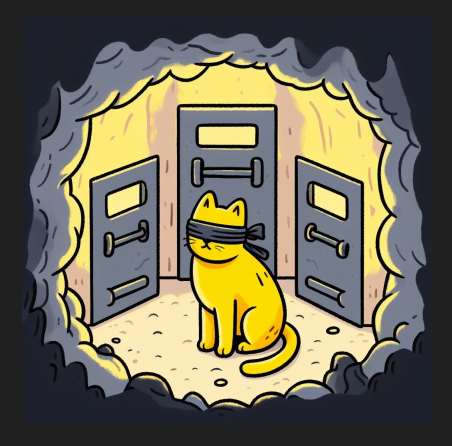

由必应生成的配图

 
N = 100000;  % 设置模拟的次数
T = zeros(N,1); % T用来存储每次模拟得到的时间
for ii = 1:N  % 开始进行 N 次模拟
    t = 0; % 初始化时间
    while 1  % 开始模拟小猫走出山洞的过程
        choose = randi(3); % 随机选择第几个门
        if choose == 1  % 选择第1个门
            t = t + 2; % 走2小时回到地面
            break % 小猫成功走出山洞，结束模拟
        elseif choose == 2  % 选择第2个门
            t = t + 4; % 走4小时回到原始出发点
        else  % 选择第3个门
            t = t + 6; % 走6小时回到原始出发点
        end
    end
    T(ii) = t;  % 记录每次模拟得到的时间
end
mean(T) % 计算所有模拟结果的平均值，即小猫走出山洞的期望时间的估计

`二分搜索法求函数零点`


$$f(x)=x^3-8x^2+x-5$$


 f(x)在区间[6,10]递增且f(6)< 0 ,f(10)>0，请用二分搜索法求零点x0（f(x0)和0的误差控制在1e-8内即可）。

% 设置初始搜索区间
a = 6;
b = 10;
% 设置误差阈值
epsilon = 1e-8;
% 开始二分搜索
while 1
    % 计算区间中点
    c = (a + b) / 2;
    % 计算中点处的函数值
    fc = c^3 - 8*c^2 + c - 5;
    % 如果中点处的函数值已经足够接近零，停止搜索
    if abs(fc) < epsilon
        break
    end
    % 否则根据函数值的正负来调整搜索区间
    if fc * (a^3 - 8*a^2 + a - 5) < 0  % f(a) × f(c)<0
        b = c;   % 区间更换为[a,c]
    else   % f(c) × f(b)<0
        a = c;   % 区间更换为[c,b]
    end
end
% 找到的零点估计值
x0 = c

x0^3 - 8*x0^2 + x0 - 5

画图看看：

close all
x = 6:0.0001:10;
y = x.^3 - 8*x.^2 + x - 5;
plot(x,y,'b-','LineWidth',2)
hold on 
plot([6,10],[0,0],'b--','LineWidth',2)
plot(x0,0,'*r','MarkerSize',10)
hold off

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)